## Lectura de capas

layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 29.830238 seconds.


## Generación de especie virtual

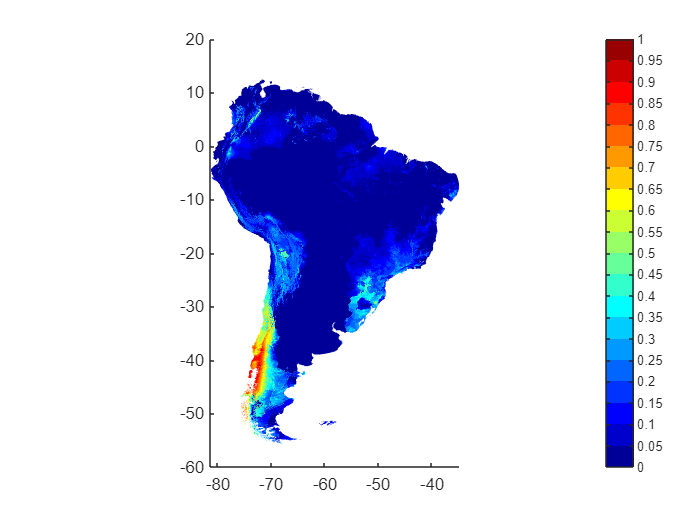

close all
InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

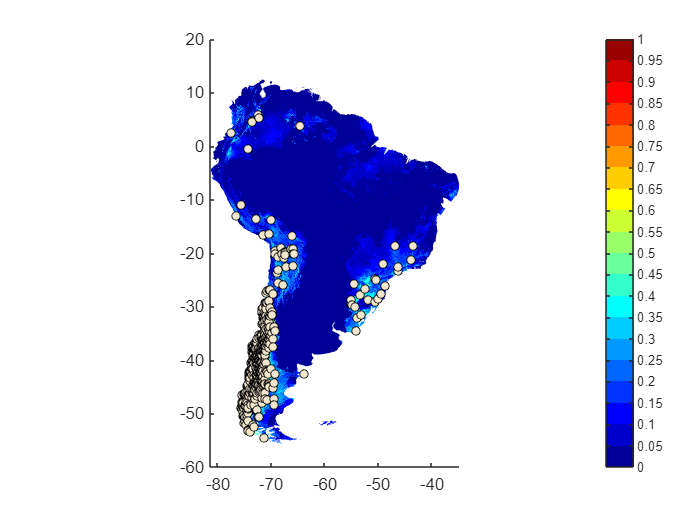

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 500, -3, true, 'GenSP', true, true);

## Modelamiento con clusters

----Finding clusters----
2 clusters identified


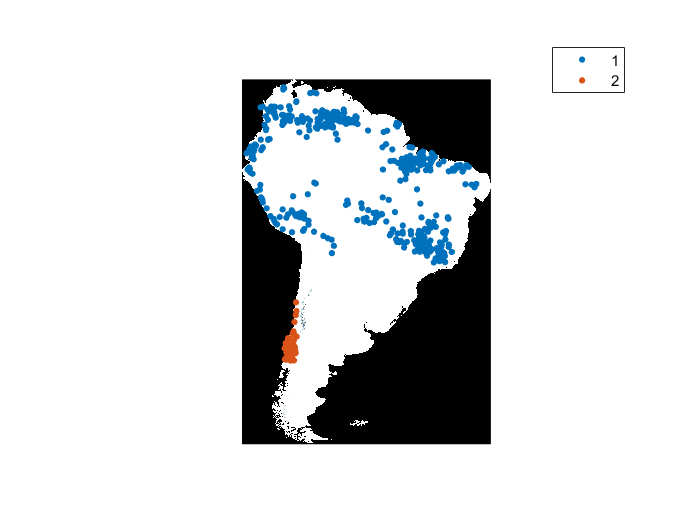

Elapsed time is 1.749477 seconds.
----Finding correlation----
Elapsed time is 5.416254 seconds.
----Creating predictors----
----Finding correlation----
Elapsed time is 6.625008 seconds.
----Creating predictors----
¡All done!
Elapsed time is 6.687529 seconds.


close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, true);

----Modeling----
-Model 1
-Model 2


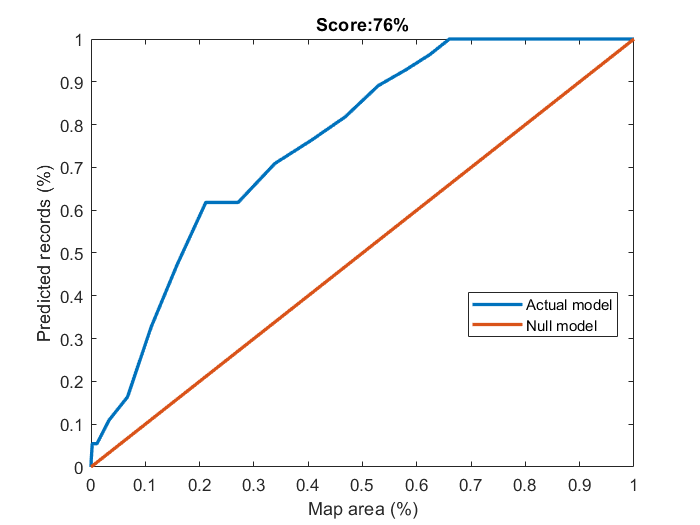

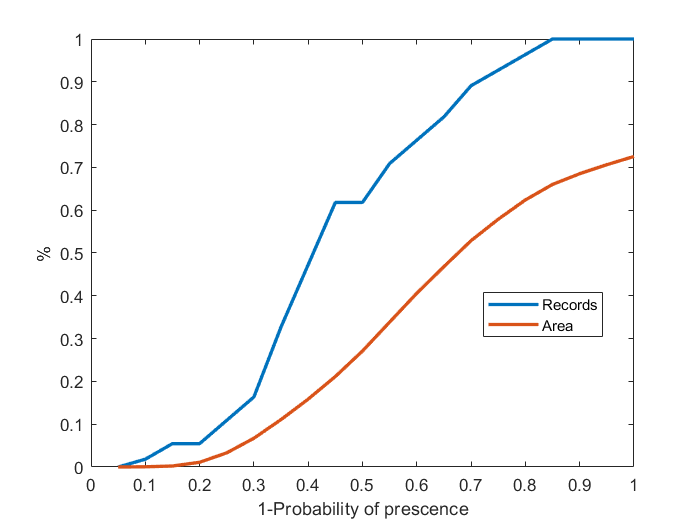

Elapsed time is 4.481229 seconds.


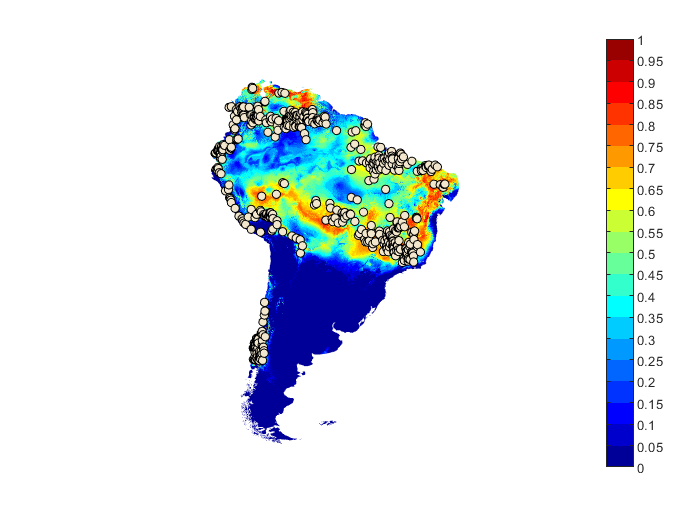

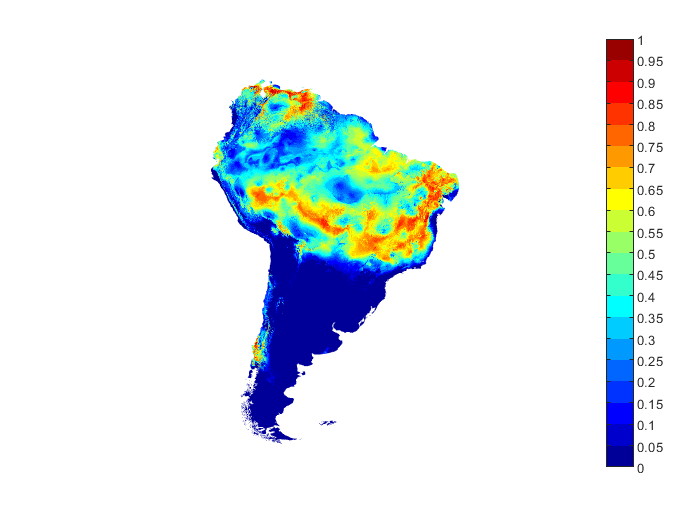

dataf = bnm_modeling(data, '', true, 4, false);

Rendimiento

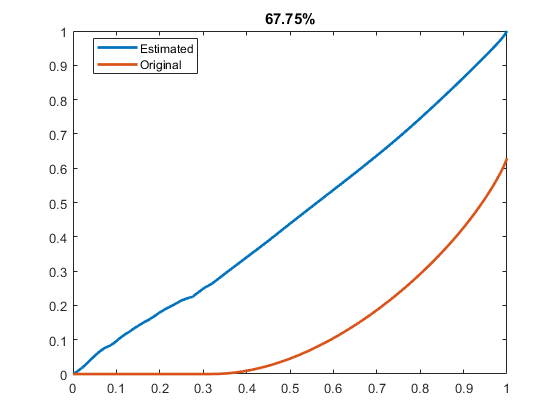

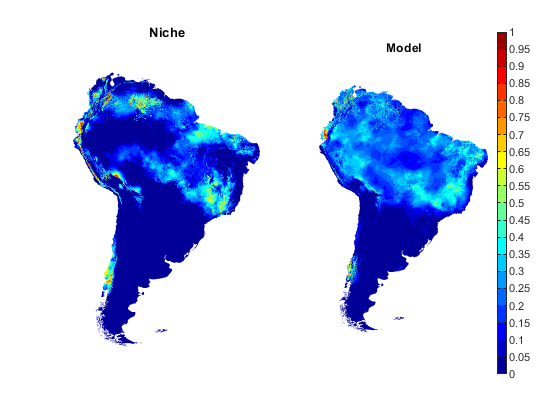

VectorMet =     0.6775    0.8645


VectorMet = MapMetric(MapInfo.Map, dataf.Map, true, dataf.R)

## Modelamiento sin clusters

close all
data2 = bnm_prep(T, Dimensions, false, 0.7, false);
data2 = bnm_modeling(data2, '', true);

## Rendimiento del modelo con clusters

VectorMet = MapMetric(MapInfo.Map, data.Map, true, data.R)

## Rendimiento del modelo sin clusters

VectorMet = MapMetric(MapInfo.Map, data2.Map, true, data2.R)